close all; clear all; clc;

% Numeric values based on fractal geometry
values.s = 0.25;
values.w = 60;
values.h = 15;
values.theta = deg2rad(0.01);
values.F_v = 12;
values.mu = 0.7;
values.Mb_max = 0;

% Output flag
verbose = true;

% Once we 

% Example solution
[F_v,r,F_f, Mb] = solve_fractal_statics(verbose,values)

[Solver]: Finding solution based on paramters...
Slip criterion exceeded. Setting F_f = F_f_max
Peel criterion reached. Setting r = r_max


F_v = 12.0021

r = 7.5000

F_f = 6

Mb = 0

% Simulation
thetas = deg2rad(180:-1:.01);
F_g_list_no_brakes = zeros(size(thetas));
F_g_list_brakes = zeros(size(thetas));

% Output flag
verbose = false;

values.Mb_max = 0

values = struct with fields:
         s: 0.2500
         w: 60
         h: 15
     theta: 1.7453e-04
       F_v: 12
        mu: 0.7000
    Mb_max: 0



% No brake sweep
for idx = 1:length(thetas)
    values.theta = thetas(idx);
    % No brake case
    values.Mb_max = 0;
    [F_g,~,~, ~] = solve_fractal_statics(verbose,values);
    F_g_list_no_brakes(idx) = F_g;
    % Brakes case
    values.Mb_max = 500;
    [F_g,~,~, ~] = solve_fractal_statics(verbose,values);
    F_g_list_brakes(idx) = F_g;
end

% Plotting
figure(1); clf; hold on; grid on;

ax = gca; % Get current axes
ax.FontSize = 16; % Set font size
ax.LineWidth = 1.5; % Set axes line width

plot(rad2deg((pi-thetas)/2),F_g_list_no_brakes/(2.*values.F_v),lineWidth = 3,color="#E39762")
plot(rad2deg((pi-thetas)/2),F_g_list_brakes/(2.*values.F_v),lineWidth = 3,color="#6280C2")
xlim([0,90])
xticks(0:15:90)

lg = legend(["No brakes","Brakes"],'FontName', 'Times New Roman','fontSize',16);
lg.FontSize = 16;
t = title("Normalized payload vs tilt angle",'fontSize',22)

t =   Text (Normalized payload vs tilt angle) with properties:

                 String: 'Normalized payload vs tilt angle'
               FontSize: 22
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [45.0001 1.2297 0]
                  Units: 'data'

  Show all properties


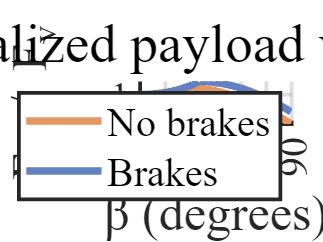

set(t, 'FontWeight', 'normal');
xlabel("β (degrees)",'FontName', 'Times New Roman','fontSize',20)
ylabel("F_g / F_v",'FontName', 'Times New Roman','fontSize',20)
set(gca, 'FontName', 'Times New Roman');

exportgraphics(gcf,'../figures/payload-comparison.png','Resolution',300)